
% Preparation
clear;
addpath(pathdef_local)

%% Script settings
LOG_FILE_BASE_NAME = 'DataLog_exp1_'; 
LOG_FILE_ENDING   = '.bin';     
INPUT_FOLDER = 'C:\Users\ge75qet\Desktop\test_1\150_30\CT_RK_SB_30_CAD/';
ENCODER_OFFSET_LOAD_TXT = 'EncoderOffsetLoad.txt';
SAMPLE_FREQ = 500;

tSample = 1 / SAMPLE_FREQ; % Sample time


## Load and save data


expData = loadRobotData_traj(tSample, INPUT_FOLDER, LOG_FILE_BASE_NAME, LOG_FILE_ENDING);

Nr. of data samples: 13029


save([INPUT_FOLDER, 'expData.mat'], '-struct', 'expData')


## Plot data

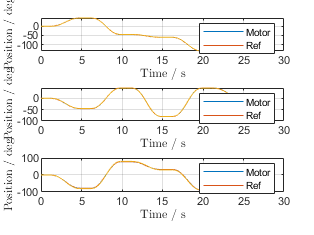

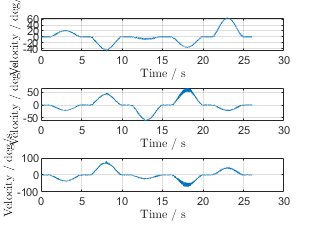

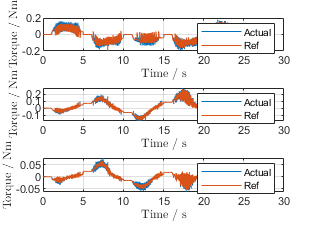

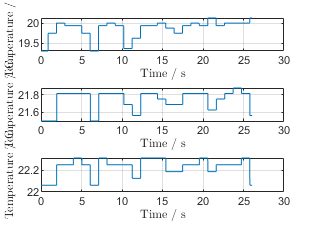


plotRobotData_traj(expData);

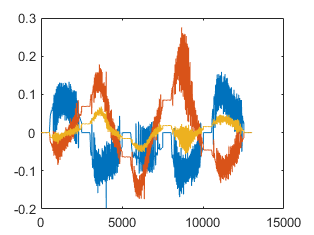


figure
plot(expData.uGes)


maeTheta = zeros(4,1);
maeOmega = zeros(4,1);

thetaMotor_traj = expData.refValuePos;
omegaMotor_traj = expData.refValueVel;

thetaMotor = expData.thetaMot;
thetaMotor_f = movmean(thetaMotor,25);
omegaMotor_f = zeros(size(thetaMotor));
omegaMotor_f(2:end-1,:) = (thetaMotor_f(3:end,:) - thetaMotor_f(1:end-2,:)) ./ (2 * tSample);

for iJoint = 1:3
    maeTheta(iJoint) = sum(abs(thetaMotor_traj(:,iJoint)-thetaMotor_f(:,iJoint)));
    maeOmega(iJoint) = sum(abs(omegaMotor_traj(:,iJoint)-omegaMotor_f(:,iJoint)));
end
maeTheta(4) = sum(abs(thetaMotor_traj(:)-thetaMotor_f(:)))

maeTheta = 1.0e+04 *

    0.4681
    0.4894
    2.1417
    3.0993


maeOmega(4) = sum(abs(omegaMotor_traj(:)-omegaMotor_f(:)))

maeOmega = 1.0e+04 *

    0.6132
    0.6346
    1.4244
    2.6722
